# **Esercitazione 2 - EEG**

**Obiettivo 1: Realizzare una funzione che permetta di caricare automaticamente i dati.**

***reminder: AD è patologico (Alzheimer's disease), C è fisiologico (healthy control)***

my_importdata;

**Obiettivo 2: Calcolare e visualizzare lo spettro di densità di potenza per ogni dato EEG.**

%DEFINISCO UN OVERLAP
overlap=30;

%DEFINISCO LA LUNGHEZZA DELLA FINESTRA TEMPORALE
window=100;

%FREQUENZA DI CAMPIONAMENTO
fs=100;

%nfft è il numero 1024
%The default nfft is the greater of 256 or the next power of 2 greater than the length of the segments.

%CODICE OKAY, PERO' PER QUANDO CHIAMAVO IL DATO DIRETTAMENTE
%[PXX1, f1] = my_pwelch(ad01, overlap, window, 1024, fs); 

%[pxx1_matlab , f1_matlab] = pwelch (ad01', window, overlap, 1024, fs );
%pmedio1_matlab= mean (pxx1_matlab,2);


%CONSIDERO I MALATI
%prendo fuori i valori del primo paziente per poi concatenare gli array di
%potenze medie
%PER ACCEDERE ALLE MATRICI RELATIVE AI PAZIENTI CHE SONO CONTENUTE NEL CELL
%ARRAY USO LA FUNZIONE cell2mat
[potenza_AD, freq_AD ]=my_pwelch(cell2mat(AD(1) ) ,overlap, window, 1024, fs);
%ciclo for che parte da 2,
for index=2:length(AD)
    [PXX, freq ]=my_pwelch(cell2mat(AD(index) ) ,overlap, window, 1024, fs);
    potenza_AD = [potenza_AD, PXX];
end

%RIPETO PER I SANI
[potenza_C, freq_C ]=my_pwelch(cell2mat(C(1) ) ,overlap, window, 1024, fs);

for index=2:length(C)
    [PXX, freq ]=my_pwelch(cell2mat(C(index) ) ,overlap, window, 1024, fs);
    potenza_C = [potenza_C, PXX];
end

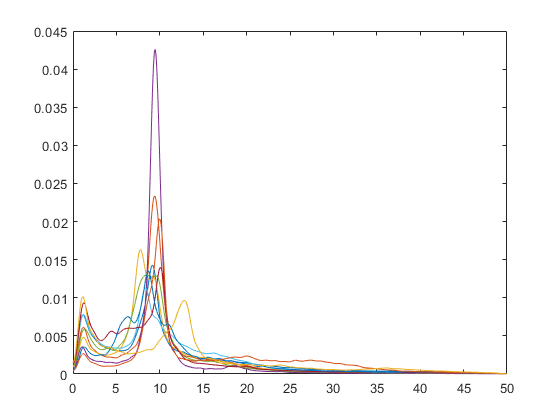

%PROVA DI PLOT
    
figure
plot(freq_AD, potenza_AD)

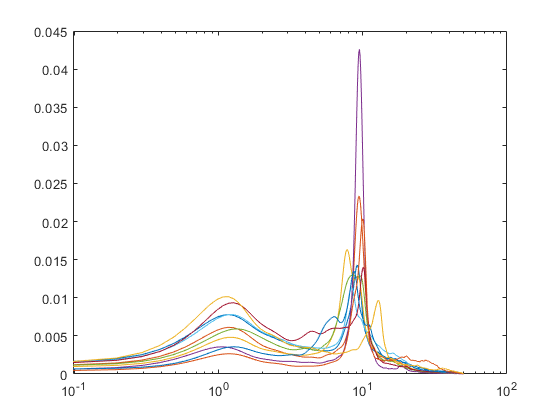

figure
semilogx(freq_AD, potenza_AD)

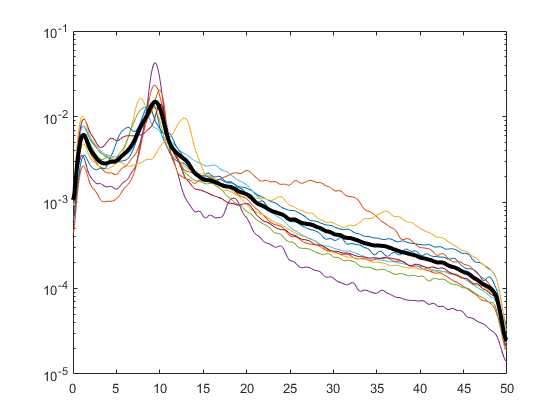

figure
semilogy(freq_AD, potenza_AD)
hold on
semilogy(freq_AD,mean (potenza_AD,2) , 'Color' , 'k' , "LineWidth", 3)

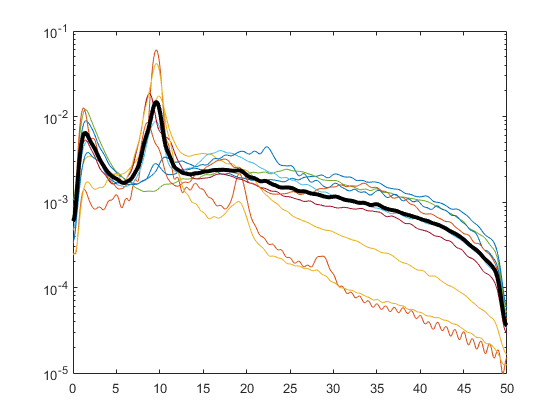

figure
semilogy(freq_C,potenza_C)
hold on
semilogy(freq_C,mean (potenza_C,2) , 'Color' , 'k' , "LineWidth", 3)

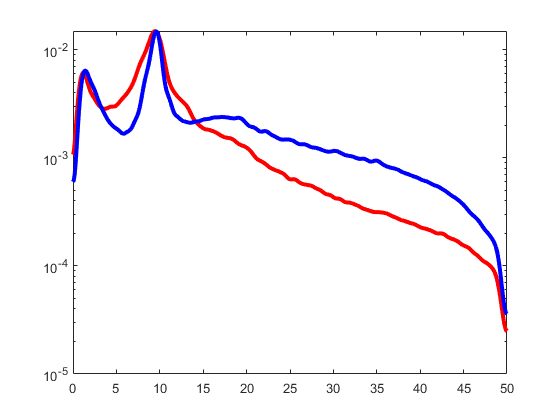

%PLOT DEGLI SPETTRI DI POTENZA MEDI
medio_AD = mean (potenza_AD,2);
medio_C = mean (potenza_C,2);

figure
semilogy(freq_AD, medio_AD , "Color", "r" , "LineWidth", 3)
hold on
semilogy(freq_C, medio_C , "Color", "b" , "LineWidth", 3)

% devstd_AD= std2(medio_AD);
% devstd_C= std2(medio_C);
% 
% y1= [10,20,30];
% y2= [1,2,3];
% x= freq_C;
% 
% where = x>0 & x<50;
% 
% opts={'EdgeColor', 'none', 'FaceColor', [0.5 0.5 1]};
% 
% [y1handle, y2handle, h] = fill_between(x, y1, y2, where, opts{:});

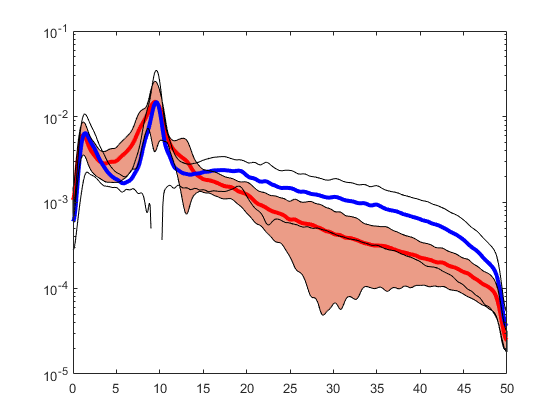

devstd_AD = std(potenza_AD, 0, 2);
devstd_C = std(potenza_C, 0, 2);

topAD = medio_AD + devstd_AD;
bottomAD = medio_AD - devstd_AD;

fill_between(freq_AD, bottomAD, topAD, 1, 'FaceColor', '#EB9C87');

topC = medio_C + devstd_C;
bottomC = medio_C - devstd_C;

fill_between(freq_AD, bottomC, topC, 1, 'EdgeColor', 'none', 'FaceColor', '#5DF597');

% figure
% semilogy(medio_AD, 'LineWidth', 2)
% hold all
% semilogy(y1)
% semilogy(y2)



%%%%MATLAB%%%%
% [PMAT10 , f_matlab] = pwelch (ad10', window, overlap, 1024, fs );
% PMAT10=mean(PMAT10);
% 
% potenzaMAT = PMAT10;
% for index = 1:9
%     pippoMAT = strcat('ad0',num2str(index));
%     pippoMAT=pippoMAT';
%     [PMAT , f_matlab] = pwelch (pippoMAT, window, overlap, 1024, fs );
%     PMAT=mean(PMAT);
%     potenzaMAT = [potenzaMAT, PMAT];
% end

% ariannaMAT=mean(potenzaMAT,2);
% figure
% semilogy(ariannaMAT)

% %%%%%%%%%%%%%%%%%%%%%%%%%%%
% 
% [PXC10, f1] = my_pwelch(c10, overlap, window, 1024, fs); 
% 
% potenza2 = PXC10;
% for index = 1:9
%     pippo1 = strcat('c0',num2str(index));
%     [PXC, f2] = my_pwelch(pippo1, overlap, window, 1024, fs); 
%     potenza2 = [potenza2, PXC];
% end
% 
% gaia=mean(potenza2,2);
% figure
% semilogy(gaia)
% %%%%%%%
% figure
% 
% semilogy(gaia)
% hold on
% semilogy(arianna)

% [PXX2, f2] = my_pwelch(ad02, overlap, window, 1024, fs); 
% [PXX3, f2] = my_pwelch(ad03, overlap, window, 1024, fs);

% [pxx_matlab , f_matlab] = pwelch (ad01', window, overlap, 1024, fs );
% pmedio_matlab= mean (pxx_matlab,2);
% figure
% semilogy(pmedio_matlab)
% [pxx_matlabc , f_matlab] = pwelch (c01', window, overlap, 1024, fs );
% pmedio_matlabc= mean (pxx_matlabc,2);
% figure
% semilogy(pmedio_matlabc)



% 
% figure
% plot(pmedio)
% hold on
% plot(pmedio_matlab)



%%%%%%%%%%%%%%%%
% pmedio = zeros(,);
% for cont=1 : 10
%     if cont<10
%         cont
%        pippo = strcat('ad0',num2str(cont),'.mat');
%        [PXX, f] = my_pwelch(pippo', overlap, window, 1024, fs); 
%        pmedio(:, cont)= pmedio + mean(PXX,2);
%     figure
%     plot(pmedio)
%     end
%     if cont==10
%         load(strcat('EEG_data/ ','ad',num2str(cont),'.mat'))
%         load(strcat('EEG_data/ ','c',num2str(cont),'.mat'))
%     end
% end



%calcolo deviazione standard



% figure
% semilogy(arianna)
% hold on
% c=arianna+desiA;
% semilogy(c)
% hold on
% ccc=arianna-desiA;
% semilogy(ccc)
% hold on
% semilogy(gaia)
% x=linspace(0,length(arianna),length(arianna));



**Obiettivo 3: Calcolare i valori di Potenza Assoluta e Relativa per ogni gruppo.**


% % % delta_A= bandpower(medio_AD,fs/2, [2 4])

%function compute_abs_real_power()
% % % %delta_A = medio_AD(freq_AD >2 & freq_AD <4);
% % % [abs_pow_A, rel_pow_A] = compute_abs_rel_power(medio_AD, freq_AD, 2, 4)
% % % [abs_pow_A, rel_pow_A] = compute_abs_rel_power(medio_AD, freq_AD, 5, 7)
% % % [abs_pow_A, rel_pow_A] = compute_abs_rel_power(medio_AD, freq_AD, 8, 13)
% % % [abs_pow_A, rel_pow_A] = compute_abs_rel_power(medio_AD, freq_AD, 14, 30)

**Obiettivo 4: Visualizzare i valori di Potenza As soluta e Relativa**